# Macro to study the impact of the RW fix on xxx on E0

# T. Lasserre

# 27/10/2019

Uniform Fit

## Common Options / General Settings

fixPar = 'E0 Bkg Norm'; % free parameter
DataType = 'Real';
FSDFlag = 'BlindingKNM2';
NonPoissonScaleFactor = 1.1;
ELossFlag = 'KatrinT2';
AnaFlag = 'StackPixel'; % uniform FPD
range = 90;
chi2 = 'chi2Stat';
RunAnaArg = {'fixPar',fixPar,'DataType',DataType,...
            'FSDFlag',FSDFlag,'ELossFlag',ELossFlag,...
            'NonPoissonScaleFactor',NonPoissonScaleFactor,...
            'AnaFlag',AnaFlag,'chi2',chi2};

## Calculate / Store Case1: Before RW Voltage Fix

RunList = 'KNM2_beforeFix';
Ab = MultiRunAnalysis(RunAnaArg{:},'RunList',RunList);

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 2 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_beforeFix
response function not avaibale in data bank 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.848410e+04,  rhoD=4.24e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.848909e+04,  rhoD=4.24e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.849410e+04,  rhoD=4.24e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.849910e+04,  rhoD=4.24e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.850409e+04,  rhoD=4.24e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.850910e+04,

ans = 1

Ab.exclDataStart = find(abs(range+Ab.RunData.qU-18575)==min(abs(range+Ab.RunData.qU-18575))); 
Ab.fixPar='1 5 6 7 8 9 10 11 12 13';
Ab.FitRunList('Recompute','ON');

Retrieve 56160 Fit Results from file
Retrieve 56161 Fit Results from file
Retrieve 56162 Fit Results from file
Retrieve 56163 Fit Results from file
Retrieve 56164 Fit Results from file
Retrieve 56165 Fit Results from file
Retrieve 56166 Fit Results from file
Retrieve 56167 Fit Results from file
Retrieve 56168 Fit Results from file
Retrieve 56169 Fit Results from file
Retrieve 56170 Fit Results from file
Retrieve 56171 Fit Results from file
Retrieve 56172 Fit Results from file
Retrieve 56173 Fit Results from file
Retrieve 56174 Fit Results from file
Retrieve 56176 Fit Results from file
Retrieve 56177 Fit Results from file
Retrieve 56178 Fit Results from file
Retrieve 56179 Fit Results from file
Retrieve 56180 Fit Results from file
Retrieve 56181 Fit Results from file
Retrieve 56182 Fit Results from file
Retrieve 56183 Fit Results from file
Retrieve 56184 Fit Results from file
Retrieve 56186 Fit Results from file
Retrieve 56187 Fit Results from file
Retrieve 56188 Fit Results from file
R

## Calculate / Store Case2: After RW Voltage Fix

RunList = 'KNM2_afterFix';
Aa = MultiRunAnalysis(RunAnaArg{:},'RunList',RunList);

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_afterFix
response function not avaibale in data bank 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.848409e+04,  rhoD=4.249e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.848910e+04,  rhoD=4.249e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.849410e+04,  rhoD=4.249e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.849910e+04,  rhoD=4.249e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.850410e+04,  rhoD=4.249e+17, Nis=8, Bmax=4.23 T, Bwgts:2.52 T 
WGTS:ComputeRF: RF, <pixel list>, qU = 1.850909e

ans = 1

Aa.exclDataStart = find(abs(range+Aa.RunData.qU-18575)==min(abs(range+Aa.RunData.qU-18575))); 
Aa.fixPar='1 5 6 7 8 9 10 11 12 13';
Aa.FitRunList('Recompute','ON');

Retrieve 56560 Fit Results from file
Retrieve 56561 Fit Results from file
Retrieve 56562 Fit Results from file
Retrieve 56563 Fit Results from file
Retrieve 56564 Fit Results from file
Retrieve 56565 Fit Results from file
Retrieve 56566 Fit Results from file
Retrieve 56575 Fit Results from file
Retrieve 56576 Fit Results from file
Retrieve 56577 Fit Results from file
Retrieve 56578 Fit Results from file
Retrieve 56579 Fit Results from file
Retrieve 56580 Fit Results from file
Retrieve 56581 Fit Results from file
Retrieve 56582 Fit Results from file
Retrieve 56583 Fit Results from file
Retrieve 56584 Fit Results from file
Retrieve 56585 Fit Results from file
Retrieve 56586 Fit Results from file
Retrieve 56587 Fit Results from file
Retrieve 56588 Fit Results from file
Retrieve 56589 Fit Results from file
Retrieve 56590 Fit Results from file
Retrieve 56591 Fit Results from file
Retrieve 56592 Fit Results from file
Retrieve 56593 Fit Results from file
Retrieve 56594 Fit Results from file
R

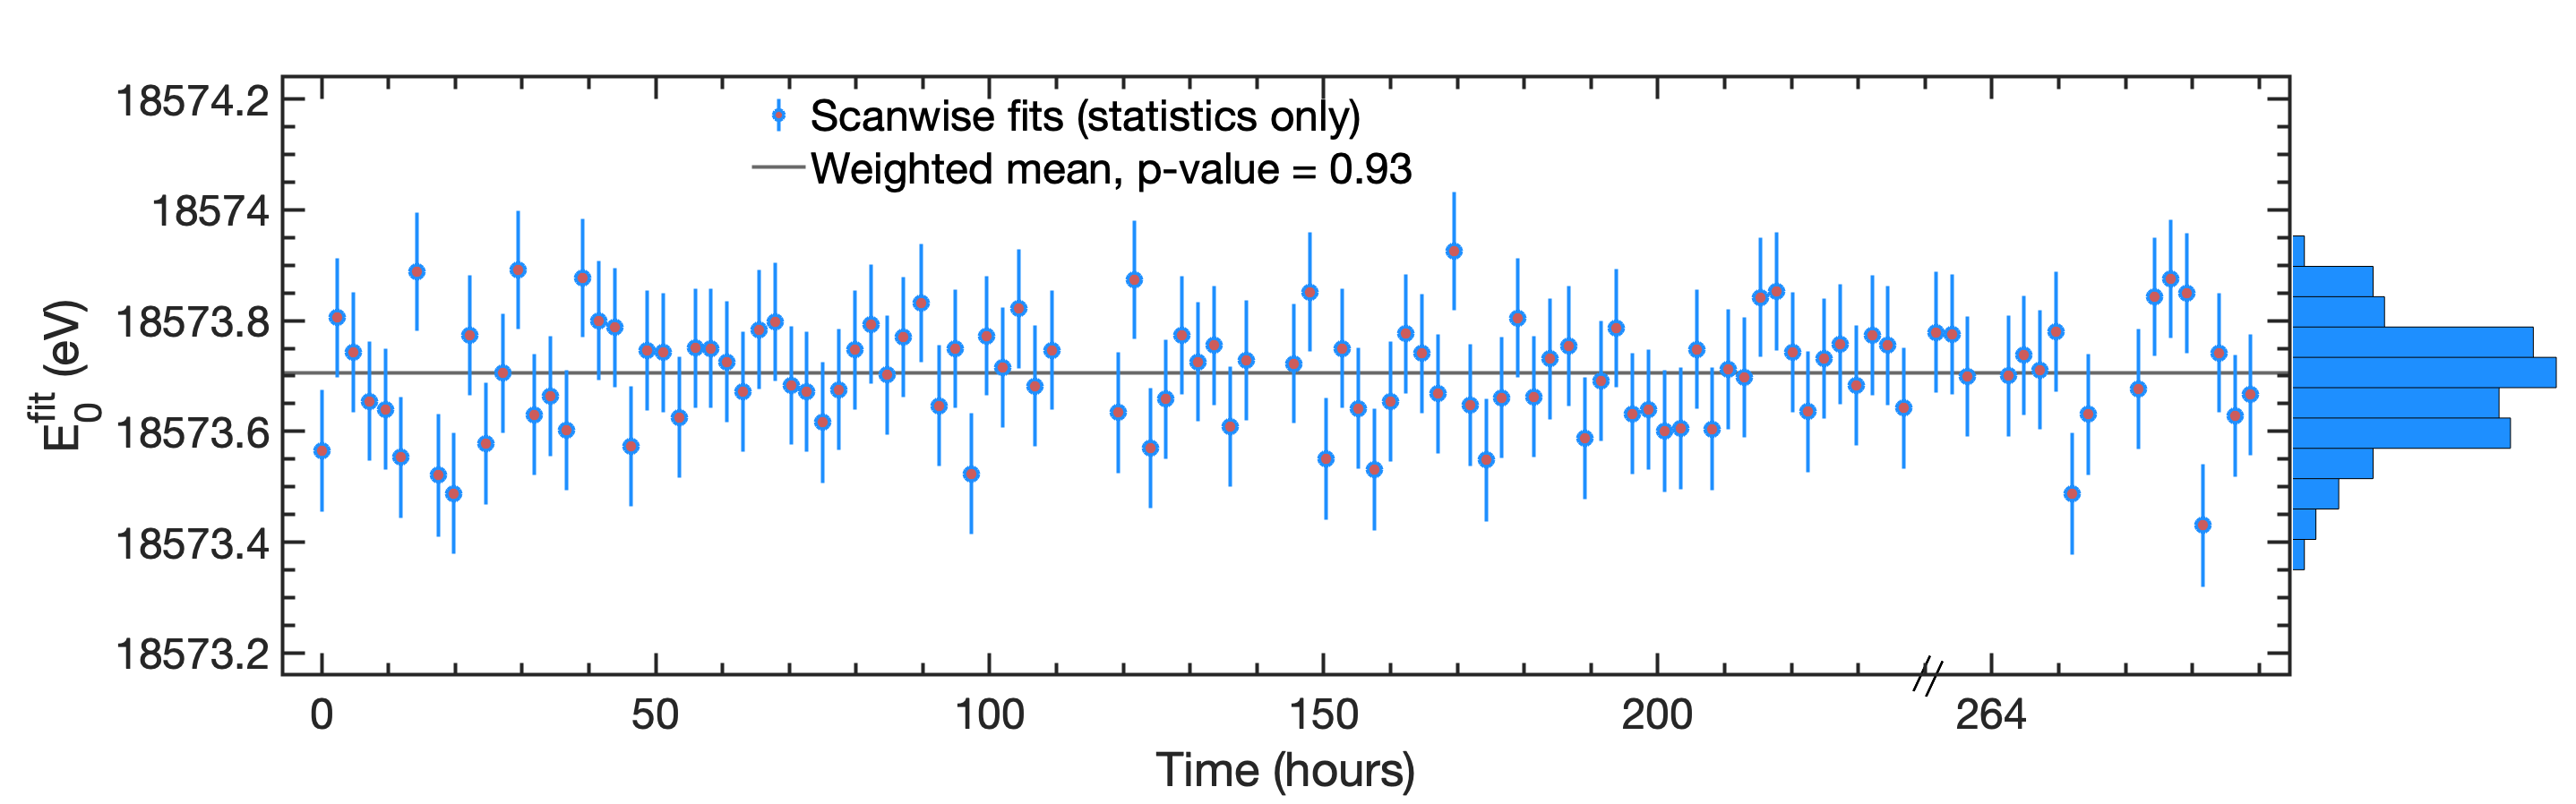

Aa.PlotFitRunList('Parameter','E0','DisplayStyle','Abs');

## Plot The Two Cases, Scan-wise

FR = Fit Results

FRb = before

FRa = after

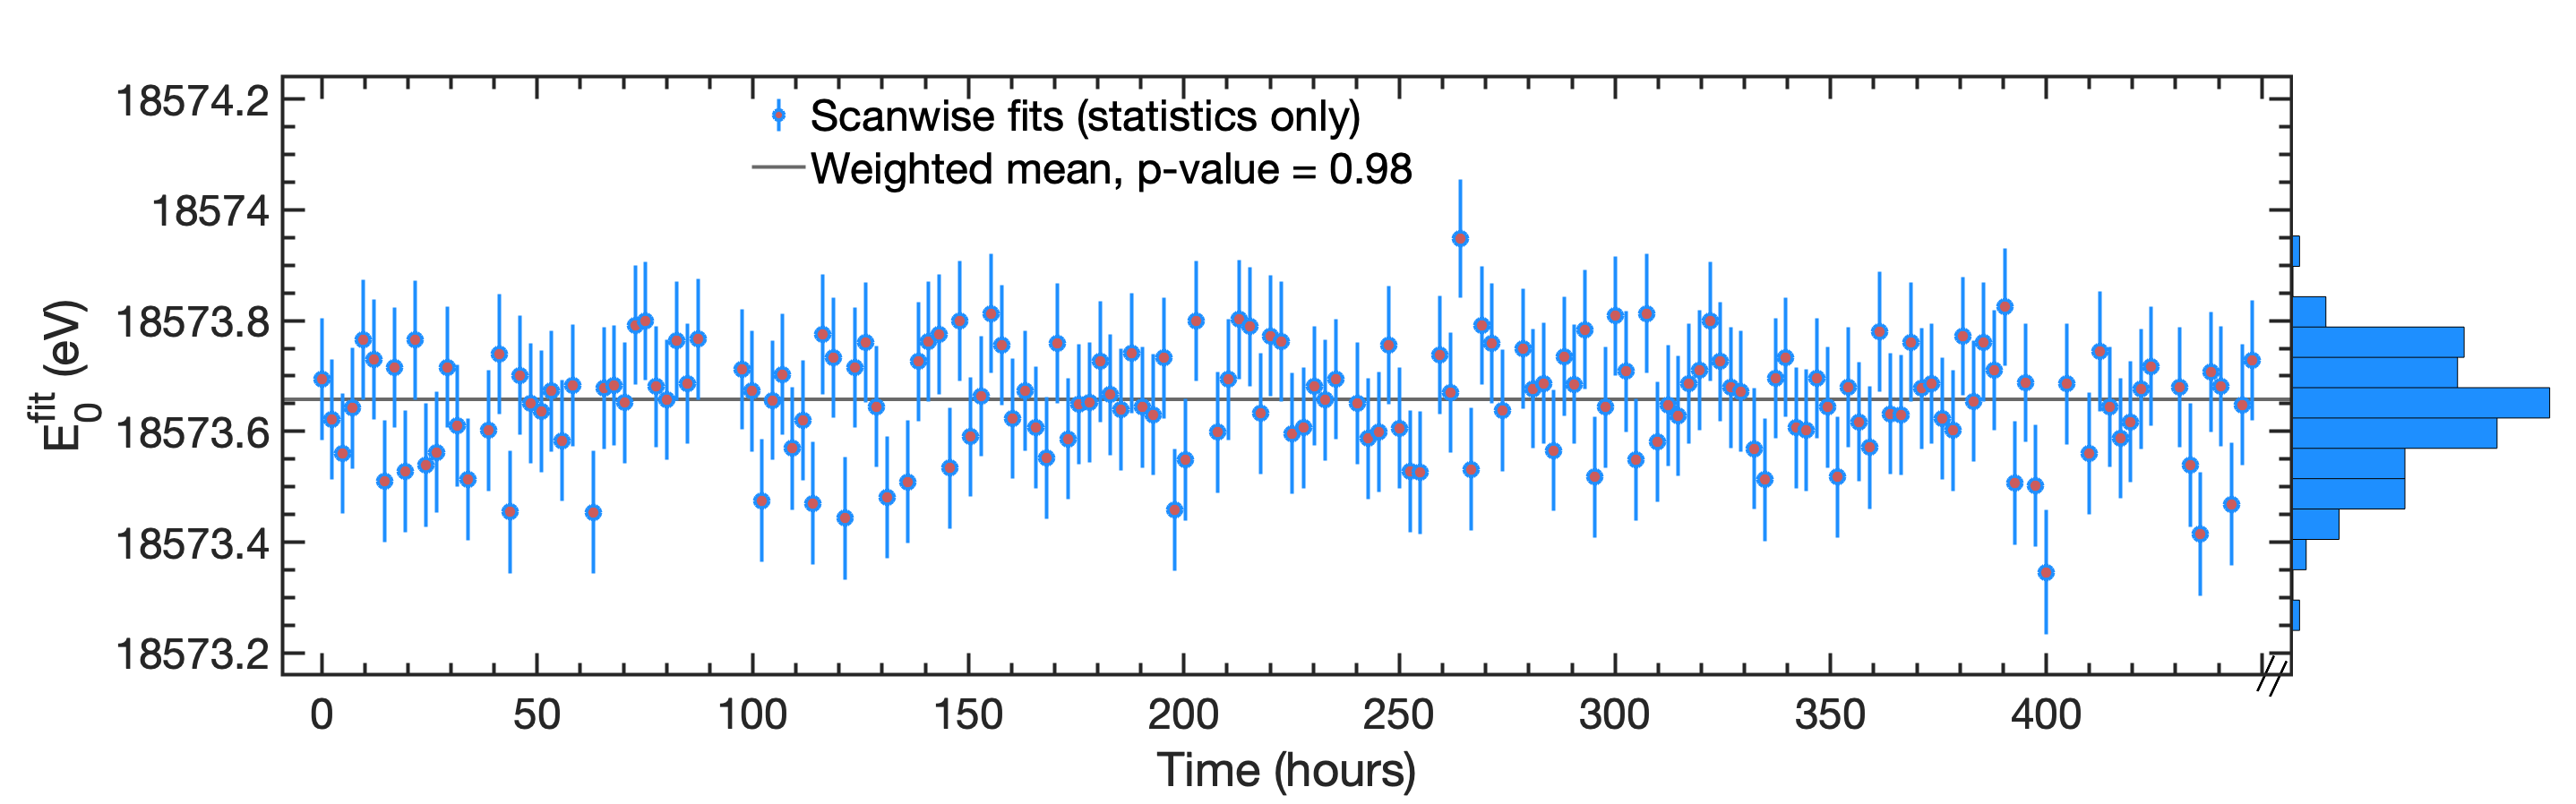

FRb = Ab.PlotFitRunList('Parameter','E0','DisplayStyle','Abs');

FRa = Aa.PlotFitRunList('Parameter','E0','DisplayStyle','Abs');

## Mean Endpoint Values Before/After

E0Before           = fitdist(FRb.E0','Normal');
E0Before_Mean      = E0Before.mu

E0Before_Mean = 1.8574e+04

E0Before_MeanError = sqrt(E0Before.ParameterCovariance(1,1))

E0Before_MeanError = 0.0074


E0After           = fitdist(FRa.E0','Normal');
E0After_Mean      = E0After.mu

E0After_Mean = 1.8574e+04

E0After_MeanError = sqrt(E0After.ParameterCovariance(1,1))

E0After_MeanError = 0.0093

## Comparison of Mean Endpoint Values Before/After RW Fixs

%Data 
b    = [1 2];
x    = [E0Before_Mean E0After_Mean];
ex   = [E0Before_MeanError E0After_MeanError];
Data = [b' x' ex'];
nbin = 2;

% Fit
parnames = 'mean'; 
ParIni   = mean([E0Before_Mean,E0After_Mean]);
Args     = {ParIni, Data, '-c', 'min; imp'};
[ par, err, chi2min, errmat ] = fminuit('Chi2Gauss',Args{:});

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'mean      '    18574.       185.74         no limits
 **********
 **    1 **MIN
 **********

 FIRST CALL TO USER FUNCTION AT NEW START POINT, WITH IFLAG=4.
 START MIGRAD MINIMIZATION.  STRATEGY 1.  CONVERGENCE WHEN EDM .LT. 0.10E-03

 FCN=   17.00147     FROM MIGRAD    STATUS=INITIATE       4 CALLS        5 TOTAL
                     EDM= unknown      STRATEGY= 1      NO ERROR MATRIX       

  EXT PARAMETER               CURRENT GUESS       STEP         FIRST   
  NO.   NAME        VALUE          ERROR          SIZE      DERIVATIVE 
   1     mean       18574.        185.74        185.74        304.77    

 MIGRAD MINIMIZATION HAS CONVERGED.

 MIGRAD WILL VERIFY CONVERGENCE AND ERROR MATRIX.
 COVARIANCE MATRIX CALCULATED SUCCESSFULLY

 FCN=   16.21953     FROM MIGRAD    STATUS=CONVERGED     14 CALLS       15 TOTAL
         

fprintf('=========================== Fit results ========================\n');

=========================== Fit results ========================


fprintf('  mean    = %.3f ± %.3f\n',par(1),err(1));

  mean    = 18573.675 ± 0.006


fprintf('  chi2min = %.2f for ndof = %d\n',chi2min,nbin-numel(ParIni));

  chi2min = 16.22 for ndof = 1


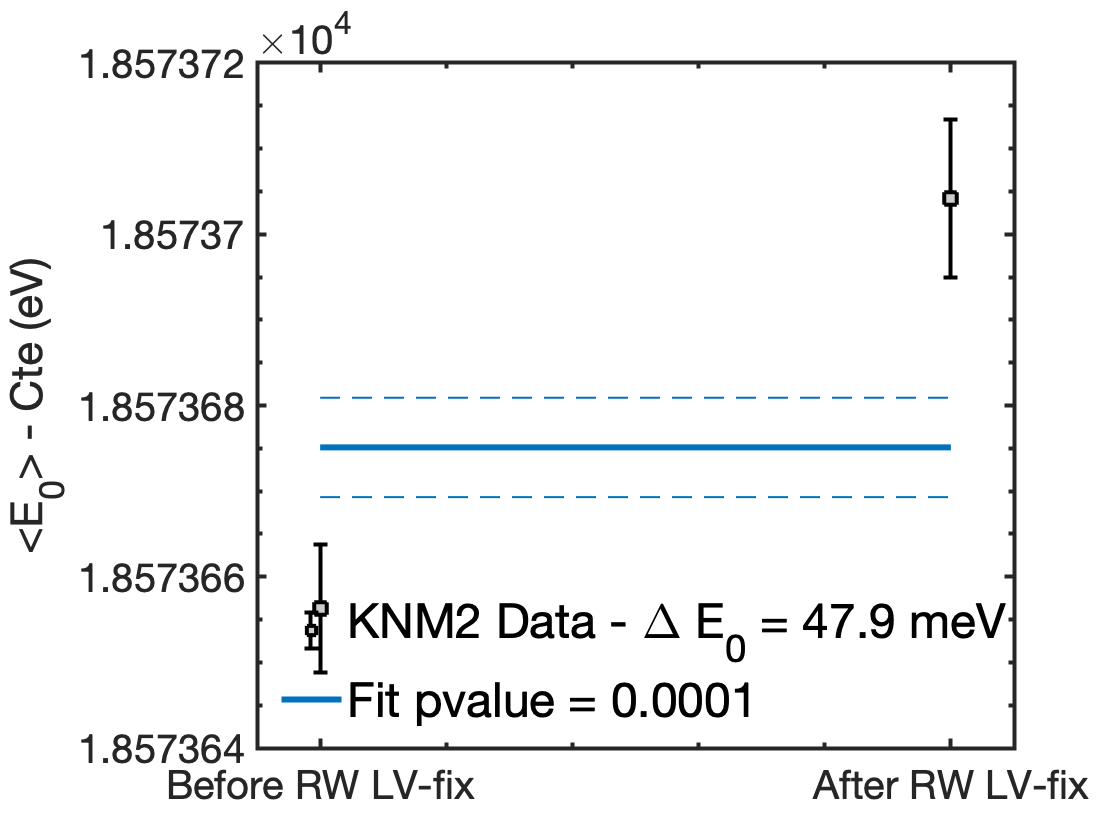


% Display
hdata = errorbar(Data(:,1),Data(:,2),Data(:,3),'ks',...
    'MarkerSize',8,'MarkerFaceColor',.8*[1 1 1],'LineWidth',2);
hold on;
hfit = line([1,2],[Model(par,Data(:,1)) Model(par,Data(:,1))],'LineWidth',3);
hfiteu = line([1,2],[Model(par+err,Data(:,1)) Model(par+err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hfited = line([1,2],[Model(par-err,Data(:,1)) Model(par-err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hold off;
ylabel('<E_0> - Cte (eV)','FontSize',24) 
legend([hdata hfit], ...
    sprintf('KNM2 Data - \\Delta E_0 = %.1f meV',(E0After_Mean-E0Before_Mean)*1e3), ...
    sprintf('Fit pvalue = %.4f',chi2pvalue(chi2min,1)),...
    'Location','SouthWest','FontSize',24)
grid off
xlim([0.9 2.1]);
xticks([1 2])
xticklabels({'Before RW LV-fix','After RW LV-fix'})
legend('boxoff');
PrettyFigureFormat('FontSize',24); 

## Discussion:

This +44.7 meV endpoint shift corresponds almost exactly to +44 mV is caused by the ampere meter (always present when this device is running). This offset was always measured to be 44+-2 mV.

The RW voltage fix consisted in a new proper grounding --> this +44 mV offset is not present anymore. The new offset is <1 mV. Then the rear wall voltage was set from -50 mV to -8 mV in order to compensate for the grounding fix. But this apparently had NO effect on the endpoint!

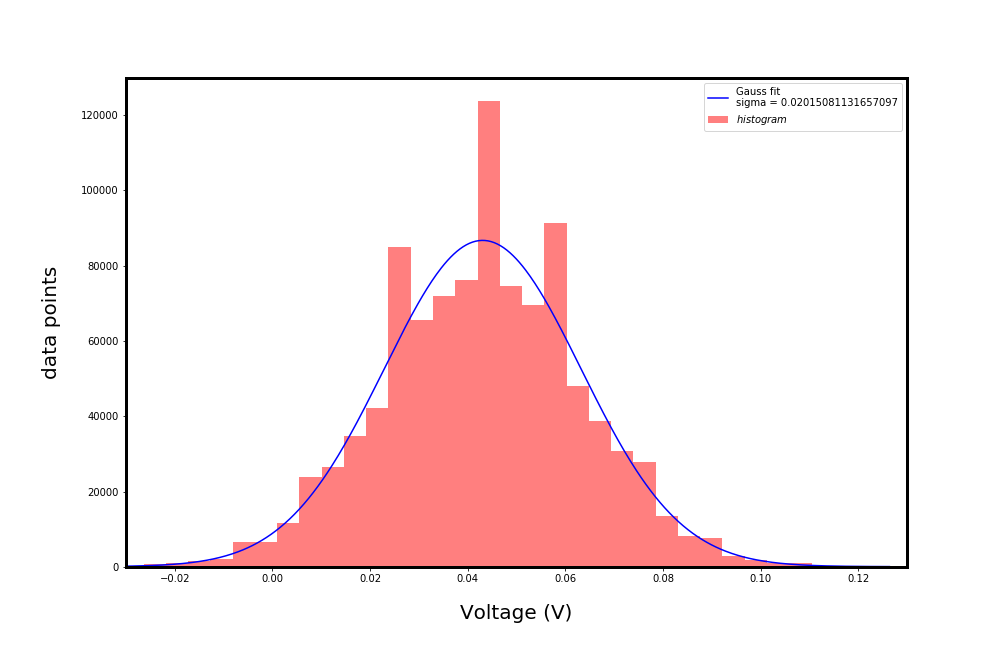

## Investigation of the Endpoint Fit Error Parameter Before / After the RW fix

Calculate the **standard error** of the mean (SEM) : it measures how far the sample mean of the data is likely to be from the true population mean

E0ErrBefore           = fitdist(FRb.E0Err','Normal');
E0ErrBefore_Mean      = E0ErrBefore.mu

E0ErrBefore_Mean = 0.1088

E0ErrBefore_MeanError = sqrt(E0ErrBefore.ParameterCovariance(1,1))

E0ErrBefore_MeanError = 8.3207e-05


E0ErrAfter           = fitdist(FRa.E0Err','Normal');
E0ErrAfter_Mean      = E0ErrAfter.mu

E0ErrAfter_Mean = 0.1083

E0ErrAfter_MeanError = sqrt(E0ErrAfter.ParameterCovariance(1,1))

E0ErrAfter_MeanError = 9.2784e-05


%Data 
b    = [1 2];
x    = [E0ErrBefore_Mean E0ErrAfter_Mean];
ex   = [E0ErrBefore_MeanError E0ErrAfter_MeanError];
Data = [b' x' ex'];
nbin = 2;

% Fit
parnames = 'mean'; 
ParIni   = mean([E0ErrBefore_Mean,E0ErrAfter_Mean]);
Args     = {ParIni, Data, '-c', 'min; imp'};
[ par, err, chi2min, errmat ] = fminuit('Chi2Gauss',Args{:});

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'mean      '   0.10857      0.10857E-02     no limits
 **********
 **    1 **MIN
 **********

 FIRST CALL TO USER FUNCTION AT NEW START POINT, WITH IFLAG=4.
 START MIGRAD MINIMIZATION.  STRATEGY 1.  CONVERGENCE WHEN EDM .LT. 0.10E-03

 FCN=   17.99880     FROM MIGRAD    STATUS=INITIATE       4 CALLS        5 TOTAL
                     EDM= unknown      STRATEGY= 1      NO ERROR MATRIX       

  EXT PARAMETER               CURRENT GUESS       STEP         FIRST   
  NO.   NAME        VALUE          ERROR          SIZE      DERIVATIVE 
   1     mean      0.10857       0.10857E-02   0.10857E-02   -14862.    

 MIGRAD MINIMIZATION HAS CONVERGED.

 MIGRAD WILL VERIFY CONVERGENCE AND ERROR MATRIX.
 COVARIANCE MATRIX CALCULATED SUCCESSFULLY

 FCN=   17.78689     FROM MIGRAD    STATUS=CONVERGED     12 CALLS       13 TOTAL
         

fprintf('=========================== Fit results ========================\n');

=========================== Fit results ========================


fprintf('  mean    = %.3f ± %.3f\n',par(1),err(1));

  mean    = 0.109 ± 0.000


fprintf('  chi2min = %.2f for ndof = %d\n',chi2min,nbin-numel(ParIni));

  chi2min = 17.79 for ndof = 1


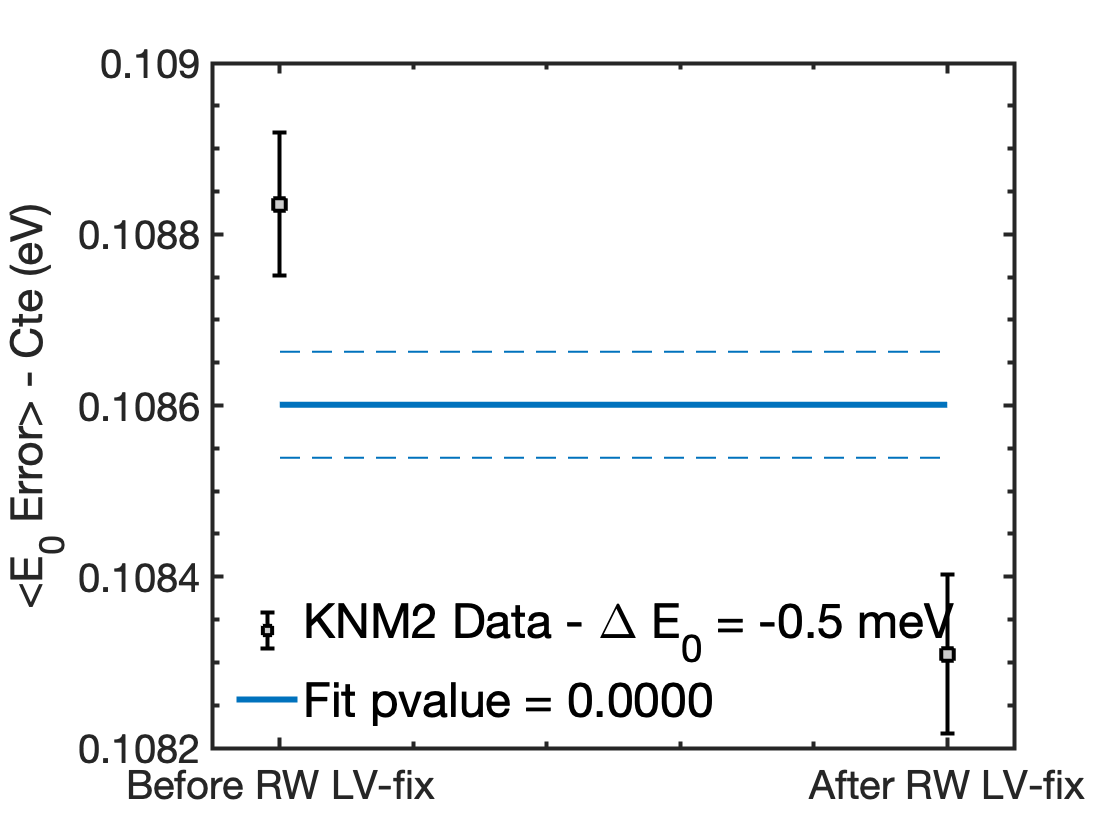


% Display
hdata = errorbar(Data(:,1),Data(:,2),Data(:,3),'ks',...
    'MarkerSize',8,'MarkerFaceColor',.8*[1 1 1],'LineWidth',2);
hold on;
hfit = line([1,2],[Model(par,Data(:,1)) Model(par,Data(:,1))],'LineWidth',3);
hfiteu = line([1,2],[Model(par+err,Data(:,1)) Model(par+err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hfited = line([1,2],[Model(par-err,Data(:,1)) Model(par-err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hold off;
ylabel('<E_0 Error> - Cte (eV)','FontSize',24) 
legend([hdata hfit], ...
    sprintf('KNM2 Data - \\Delta E_0 = %.1f meV',(E0ErrAfter_Mean-E0ErrBefore_Mean)*1e3), ...
    sprintf('Fit pvalue = %.4f',chi2pvalue(chi2min,1)),...
    'Location','SouthWest','FontSize',24)
grid off
xlim([0.9 2.1]);
xticks([1 2])
xticklabels({'Before RW LV-fix','After RW LV-fix'})
legend('boxoff');
PrettyFigureFormat('FontSize',24); 

## Investigation of the variance of the endpoint fit Before / After the RW fix

Calculate Variance E0 Before Fix

SigmaE0before = std(FRb.E0); 
SigmaE0STDbefore = sqrt((2*SigmaE0before^4)/(numel(FRb.E0)-1));
fprintf('E0 standard deviation before fix = %.1f +- %.1f meV',SigmaE0before*1e3,SigmaE0STDbefore*1e3);

E0 standard deviation before fix = 97.4 +- 1.0 meV

Calculate Variance E0 After Fix

SigmaE0after= std(FRa.E0); 
SigmaE0STDafter = sqrt((2*SigmaE0after^4)/(numel(FRa.E0)-1));
fprintf('E0 standard deviation after fix = %.1f +- %.1f meV',SigmaE0after*1e3,SigmaE0STDafter*1e3);

E0 standard deviation after fix = 97.6 +- 1.3 meV

The standard deviation seems slightly reduced. It seems to be significant!

%Data 
b    = [1 2];
x    = [SigmaE0before SigmaE0after];
ex   = [SigmaE0STDbefore SigmaE0STDafter];
Data = [b' x' ex'];
nbin = 2;

% Fit
parnames = 'mean'; 
ParIni   = mean([SigmaE0before,SigmaE0before]);
Args     = {ParIni, Data, '-c', 'min; imp'};
[ par, err, chi2min, errmat ] = fminuit('Chi2Gauss',Args{:});

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'mean      '   0.97378E-01  0.97378E-03     no limits
 **********
 **    1 **MIN
 **********

 FIRST CALL TO USER FUNCTION AT NEW START POINT, WITH IFLAG=4.
 START MIGRAD MINIMIZATION.  STRATEGY 1.  CONVERGENCE WHEN EDM .LT. 0.10E-03

 FCN=  0.1814143E-01 FROM MIGRAD    STATUS=INITIATE       4 CALLS        5 TOTAL
                     EDM= unknown      STRATEGY= 1      NO ERROR MATRIX       

  EXT PARAMETER               CURRENT GUESS       STEP         FIRST   
  NO.   NAME        VALUE          ERROR          SIZE      DERIVATIVE 
   1     mean      0.97378E-01   0.97378E-03   0.97378E-03   -209.93    

 MIGRAD MINIMIZATION HAS CONVERGED.

 MIGRAD WILL VERIFY CONVERGENCE AND ERROR MATRIX.
 COVARIANCE MATRIX CALCULATED SUCCESSFULLY

 FCN=  0.1104511E-01 FROM MIGRAD    STATUS=CONVERGED     12 CALLS       13 TOTAL
         

fprintf('=========================== Fit results ========================\n');

=========================== Fit results ========================


fprintf('  mean    = %.3f ± %.3f\n',par(1),err(1));

  mean    = 0.097 ± 0.001


fprintf('  chi2min = %.2f for ndof = %d\n',chi2min,nbin-numel(ParIni));

  chi2min = 0.01 for ndof = 1


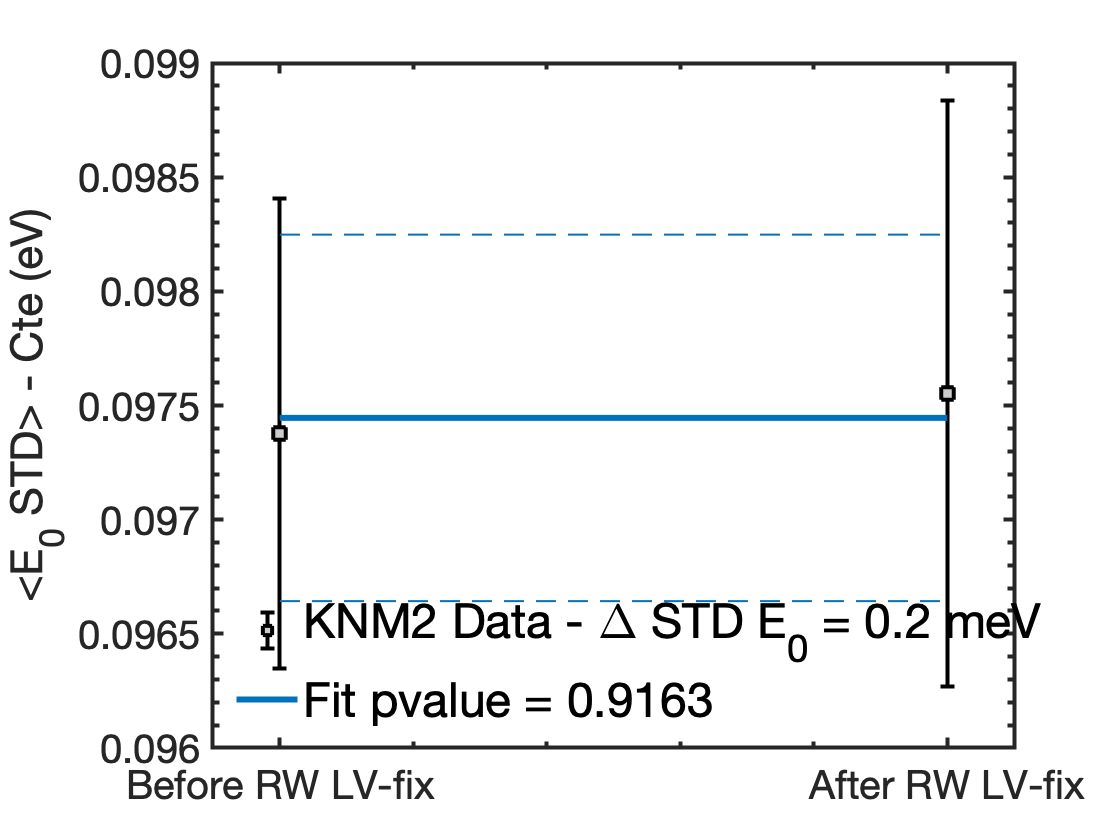


% Display
hdata = errorbar(Data(:,1),Data(:,2),Data(:,3),'ks',...
    'MarkerSize',8,'MarkerFaceColor',.8*[1 1 1],'LineWidth',2);
hold on;
hfit = line([1,2],[Model(par,Data(:,1)) Model(par,Data(:,1))],'LineWidth',3);
hfiteu = line([1,2],[Model(par+err,Data(:,1)) Model(par+err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hfited = line([1,2],[Model(par-err,Data(:,1)) Model(par-err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hold off;
ylabel('<E_0 STD> - Cte (eV)','FontSize',24) 
legend([hdata hfit], ...
    sprintf('KNM2 Data - \\Delta STD E_0 = %.1f meV',(SigmaE0after-SigmaE0before)*1e3), ...
    sprintf('Fit pvalue = %.4f',chi2pvalue(chi2min,1)),...
    'Location','SouthWest','FontSize',24)
grid off
xlim([0.9 2.1]);
xticks([1 2])
xticklabels({'Before RW LV-fix','After RW LV-fix'})
legend('boxoff');
PrettyFigureFormat('FontSize',24); 

## Investigation of the Normalization Fit Parameter Before / After the RW fix

%Data 
NBefore           = fitdist(FRb.N','Normal');
NBefore_Mean      = NBefore.mu

NBefore_Mean = -0.0409

NBefore_MeanError = sqrt(NBefore.ParameterCovariance(1,1))

NBefore_MeanError = 3.2025e-04


NAfter           = fitdist(FRa.N','Normal');
NAfter_Mean      = NAfter.mu

NAfter_Mean = -0.0400

NAfter_MeanError = sqrt(NAfter.ParameterCovariance(1,1))

NAfter_MeanError = 3.5842e-04



b    = [1 2];
x    = [NBefore_Mean NAfter_Mean];
ex   = [NBefore_MeanError NAfter_MeanError];
Data = [b' x' ex'];
nbin = 2;

% Fit
parnames = 'mean'; 
ParIni   = mean([NBefore_Mean,NAfter_Mean]);
Args     = {ParIni, Data, '-c', 'min; imp'};
[ par, err, chi2min, errmat ] = fminuit('Chi2Gauss',Args{:});

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'mean      '  -0.40411E-01  0.40411E-03     no limits
 **********
 **    1 **MIN
 **********

 FIRST CALL TO USER FUNCTION AT NEW START POINT, WITH IFLAG=4.
 START MIGRAD MINIMIZATION.  STRATEGY 1.  CONVERGENCE WHEN EDM .LT. 0.10E-03

 FCN=   3.553939     FROM MIGRAD    STATUS=INITIATE       4 CALLS        5 TOTAL
                     EDM= unknown      STRATEGY= 1      NO ERROR MATRIX       

  EXT PARAMETER               CURRENT GUESS       STEP         FIRST   
  NO.   NAME        VALUE          ERROR          SIZE      DERIVATIVE 
   1     mean     -0.40411E-01   0.40411E-03   0.40411E-03    1770.4    

 MIGRAD MINIMIZATION HAS CONVERGED.

 MIGRAD WILL VERIFY CONVERGENCE AND ERROR MATRIX.
 COVARIANCE MATRIX CALCULATED SUCCESSFULLY

 FCN=   3.509254     FROM MIGRAD    STATUS=CONVERGED     12 CALLS       13 TOTAL
         

fprintf('=========================== Fit results ========================\n');

=========================== Fit results ========================


fprintf('  mean    = %.3f ± %.3f\n',par(1),err(1));

  mean    = -0.040 ± 0.000


fprintf('  chi2min = %.2f for ndof = %d\n',chi2min,nbin-numel(ParIni));

  chi2min = 3.51 for ndof = 1


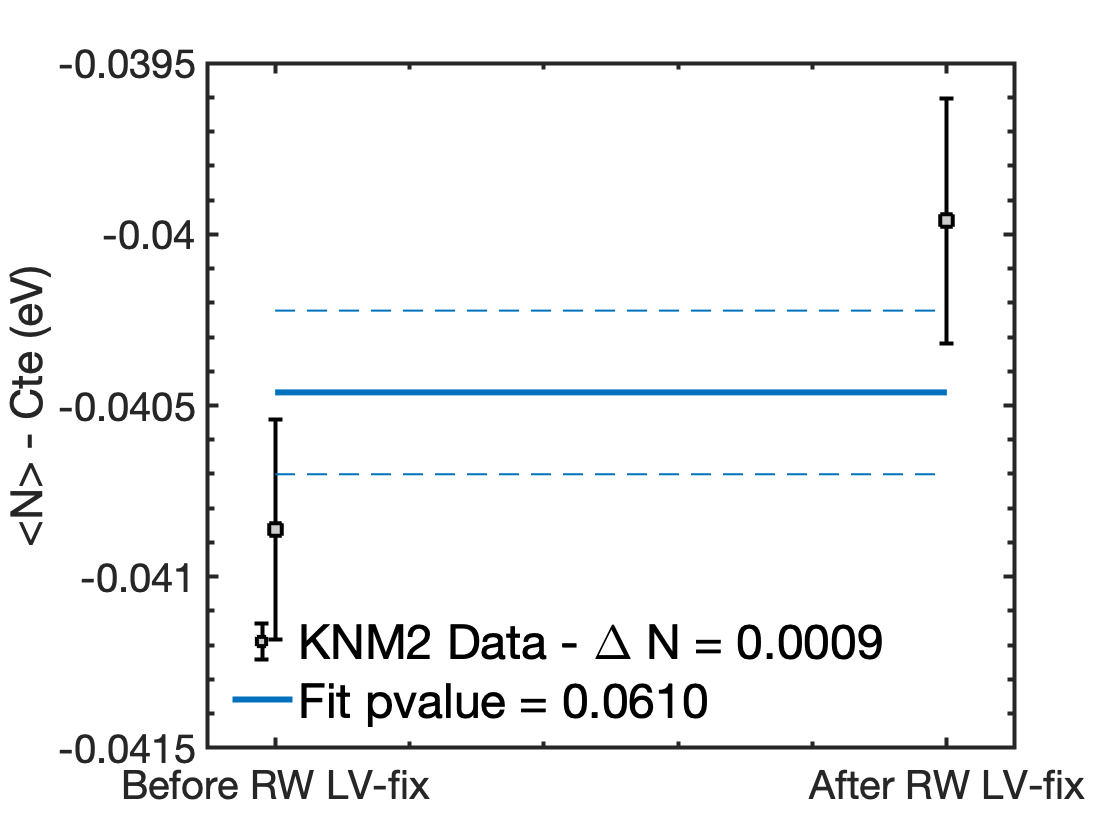


% Display
hdata = errorbar(Data(:,1),Data(:,2),Data(:,3),'ks',...
    'MarkerSize',8,'MarkerFaceColor',.8*[1 1 1],'LineWidth',2);
hold on;
hfit = line([1,2],[Model(par,Data(:,1)) Model(par,Data(:,1))],'LineWidth',3);
hfiteu = line([1,2],[Model(par+err,Data(:,1)) Model(par+err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hfited = line([1,2],[Model(par-err,Data(:,1)) Model(par-err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hold off;
ylabel('<N> - Cte (eV)','FontSize',24) 
legend([hdata hfit], ...
    sprintf('KNM2 Data - \\Delta N = %.3g',(NAfter_Mean-NBefore_Mean)), ...
    sprintf('Fit pvalue = %.4f',chi2pvalue(chi2min,1)),...
    'Location','SouthWest','FontSize',24)
grid off
xlim([0.9 2.1]);
xticks([1 2])
xticklabels({'Before RW LV-fix','After RW LV-fix'})
legend('boxoff');
PrettyFigureFormat('FontSize',24); 